In economics we solve a lot of optimization problems. A standard problem is of a household maximizing utility subject to a budget constraint. We will solve this below.

Our household will have log utility of consumption and log utility of leisure. They get income from working and there is no saving, so c = w*h

w = 3.;
alpha_h = 1.5;
assets = 0;
ufun = @(h) log(w*h + assets) + alpha_h*log(1 - h);
ufun(0.5)

ans = -0.6343

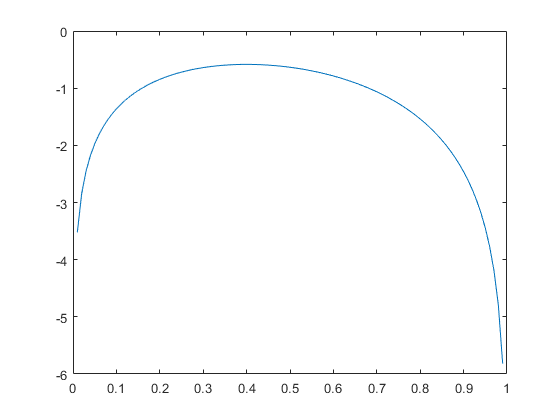

hgrid = 0:0.01:0.99;
plot(hgrid, ufun(hgrid))

We see from the plot that this utility function has a maximum around 0.5. We can find it with the fminunc function. 

Note: fminunc solves a minimization problem. We need to pass it the negative to find a maximum

ret = fminunc(@(h) -ufun(h), 0.2)


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



ret = 0.4000

We found the minimum. 

**Exercise**: Try adjusting the parameters in the model. To do this, go to the block with the picture and change w or alpha_h to a different number, then re-execute the cell by hitting ctrl-enter. You should see the plot change. Next, come back to the block above and execute fminunc again.

You should find that changing w does nothing to the optimal hours worked. This is because the income and substitution effects perfectly cancel each other out with this utlity function.

Raising assets will lower optimal hours. This is the income (or wealth) effect. In fact, if you make assets larger than 3, optimal hours is negative. This is impossible, so we would need to impose a non-negativity constraint.

fminunc also solves multivariate optimization problems. Here is a family labor supply example.

w1 = 3.;
w2 = 2.;
alpha_h = 1.5;
assets = 0;
ufun = @(h) log(w1*h(1) + w2*h(2) + assets) + alpha_h*log(1 - h(1)) + alpha_h*log(1 - h(2));
ufun([0.5; 0.5])

ans = -1.1632

ret = fminunc(@(h) -ufun(h), [0.5;0.5])


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



ret =     0.3750
    0.0625


We see that it is optimal for family member 1 to work more (0.375 hours) because they have a higher wage. However, family member 2 still works a bit.

Here we solved a constrained optimization problem by substituting the constraint into the utility function and solving a univariate optimization problem. This is usually the easiest way to do these things. If you can't do this and need to solve a complicated constrained optimization problem, type "doc fmincon" or just use JuMP in Julia, which is easier to use.